clear
B = [1 1 3; 1 2 4; 1 1 3;]

B =      1     1     3
     1     2     4
     1     1     3


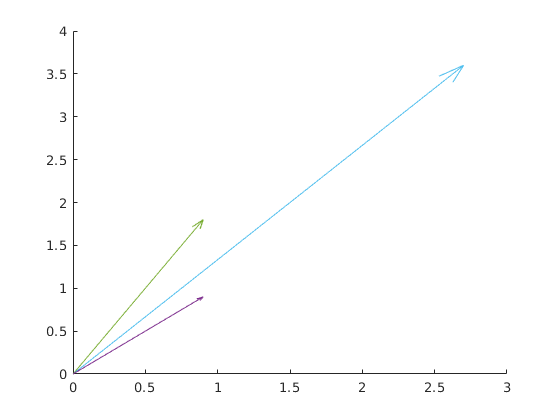


hold on
quiver3(0, 0, 0, 1, 1, 1)
quiver3(0, 0, 0, 1, 2, 1)
quiver3(0, 0, 0, 3, 4, 3)


det(B)

ans = 0

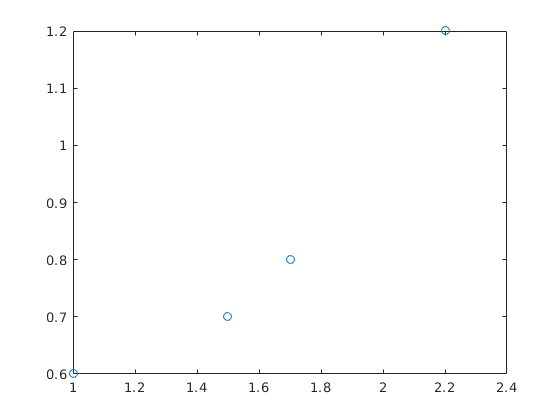

d1 = [2.2; 1.2];
d2 = [1; 0.6];
d3 = [1.5; 0.7];
d4 = [1.7; 0.8];

plot([2.2 1 1.5 1.7], [1.2 0.6 0.7 0.8], 'o');


u2 = [2; 1];
u1 = [cosd(90) -sind(90); sind(90) cosd(90)] * u2;
u = [u1 u2];
d1_c = inv(u) * d1;
d2_c = inv(u) * d2;
d3_c = inv(u) * d3;
d4_c = inv(u) * d4;

d1r = u1 * d1_c(1);
d2r = u1 * d2_c(1);
d3r = u1 * d3_c(1);
d4r = u1 * d4_c(1);

dr = [d1r d2r d3r d4r]

dr =    -0.0400   -0.0400    0.0200    0.0200
    0.0800    0.0800   -0.0400   -0.0400


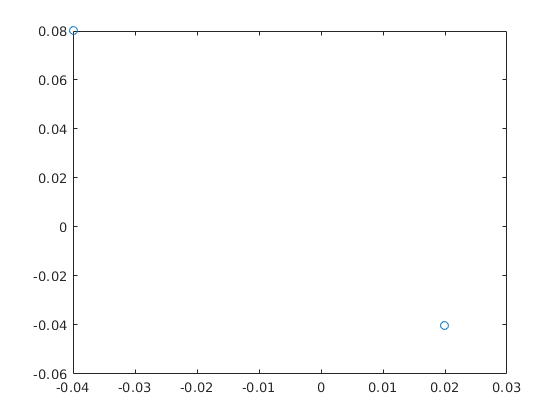


plot(dr(1, :), dr(2, :), 'o')